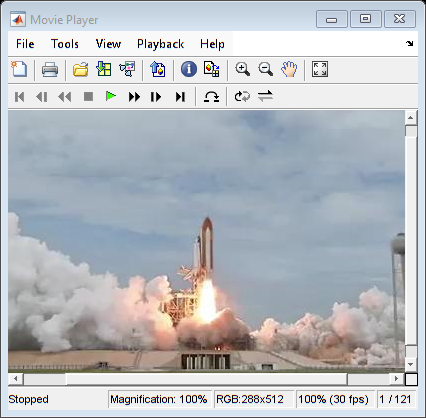

implay("shuttle.avi")

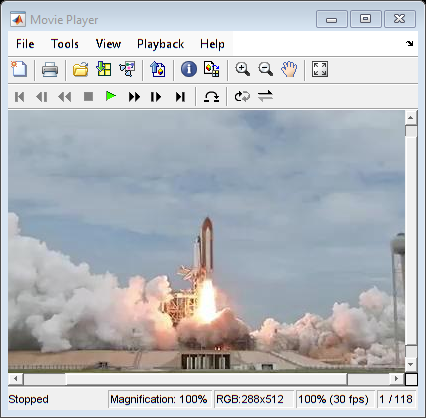

% Read the video
video = VideoReader('shuttle.avi');

% Create a VideoWriter object to save the new video
outputVideo = VideoWriter('shuttle_trimmed.avi');
outputVideo.FrameRate = video.FrameRate;
open(outputVideo);

% Get total number of frames
numFrames = floor(video.Duration * video.FrameRate);

% Loop through all frames except the last 3
for i = 1:numFrames - 3
    frame = readFrame(video);
    writeVideo(outputVideo, frame);
end

% Close the writer
close(outputVideo);

% Optionally play the trimmed video
implay('shuttle_trimmed.avi');

video = VideoReader('shuttle.avi');
frameRate = video.FrameRate;                 % frames per second
numFrames = floor(video.Duration * frameRate);
newNumFrames = numFrames - 3;
newDuration = newNumFrames / frameRate

newDuration = 3.9333

video = VideoReader('shuttle_trimmed.avi');  % Replace with actual filename

% Preallocate if needed
masks = {};  % Store masks for each frame

frameIdx = 1;

while hasFrame(video)
    frame = readFrame(video);
    
    % Convert to grayscale
    grayFrame = im2gray(frame);  % Or rgb2gray(frame) for older MATLAB versions
    
    % Create binary mask
    flameMask = grayFrame > 245;

    % Save the mask
    masks{frameIdx} = flameMask;
    
    % (Optional) Display mask
    % imshow(flameMask); drawnow;
    
    frameIdx = frameIdx + 1;
end

video = VideoReader('shuttle_trimmed.avi');  % Replace with correct file name

% Read first frame
firstFrame = readFrame(video);
firstGray = im2gray(firstFrame);
firstMask = firstGray > 245;
firstTrueCount = nnz(firstMask);  % Count of true pixels in first frame

% Read through to the last frame
while hasFrame(video)
    lastFrame = readFrame(video);
end
lastGray = im2gray(lastFrame);
lastMask = lastGray > 245;
lastTrueCount = nnz(lastMask);  % Count of true pixels in last frame

% Calculate difference
diffTruePixels = lastTrueCount - firstTrueCount;

% Display result
fprintf('Difference in true pixels (last - first): %d\n', diffTruePixels);

Difference in true pixels (last - first): 2546
